# Plot from the data of main

    % If you want to use the workspace data, make this value true
useWorkspaceData = false;

if useWorkspaceData == false
    clear all;
    clc;
    warning('off');
    useWorkspaceData = false;
end

## Selecting the data

testData = true;

#### Select data name and folder

    %% TEST DATA
if testData == true 
    fileName = "moving.mat";
    folderName = "..\output\testing";
    pathName = fullfile(folderName, fileName);
else
    %% CHOOSEN DATA

    fileName = "Rl_5.0_Ra_0.1_test_direct.mat";
    folderName = "..\output\opt\R";
    pathName = fullfile(folderName, fileName);
end

if useWorkspaceData == false
    load(pathName);
end

#### Total time of the simulation in seconds

disp("Total time: " + num2str(step_time(i)) + " seconds");

Total time: 826.9074 seconds


## Dynamic plot

% figure; 
% set(gcf,'Visible','on'); hold on; grid on;
% sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), x_f(:, 1), N, obstacles);
% tit = title("Iteration 1, time: 0s");
% 
% for ip = 1 : i - 1
% 
%         % Do the plotting
%     sp.updateLeaderPath(x_l(:,ip), X_L_plot(:,:,ip));
%     sp.updateLoadPos(x_l(:,ip), x_f(:,ip), loadTheta_p(ip) - pi/4);
%     sp.updateFollowerPath(x_f(:,ip), X_F_plot(:,:,ip));
% 
%     if size(obstacles, 1) ~= 0
%         sp.updateObstacles(obstacles, size(obstacles, 1))
%     end
% 
%     tit.String = "Iteration: " + num2str(ip) + ", time: " + num2str(ip*sys.Ts) + "s";
%     sp.redraw();
% end

#### Save gif

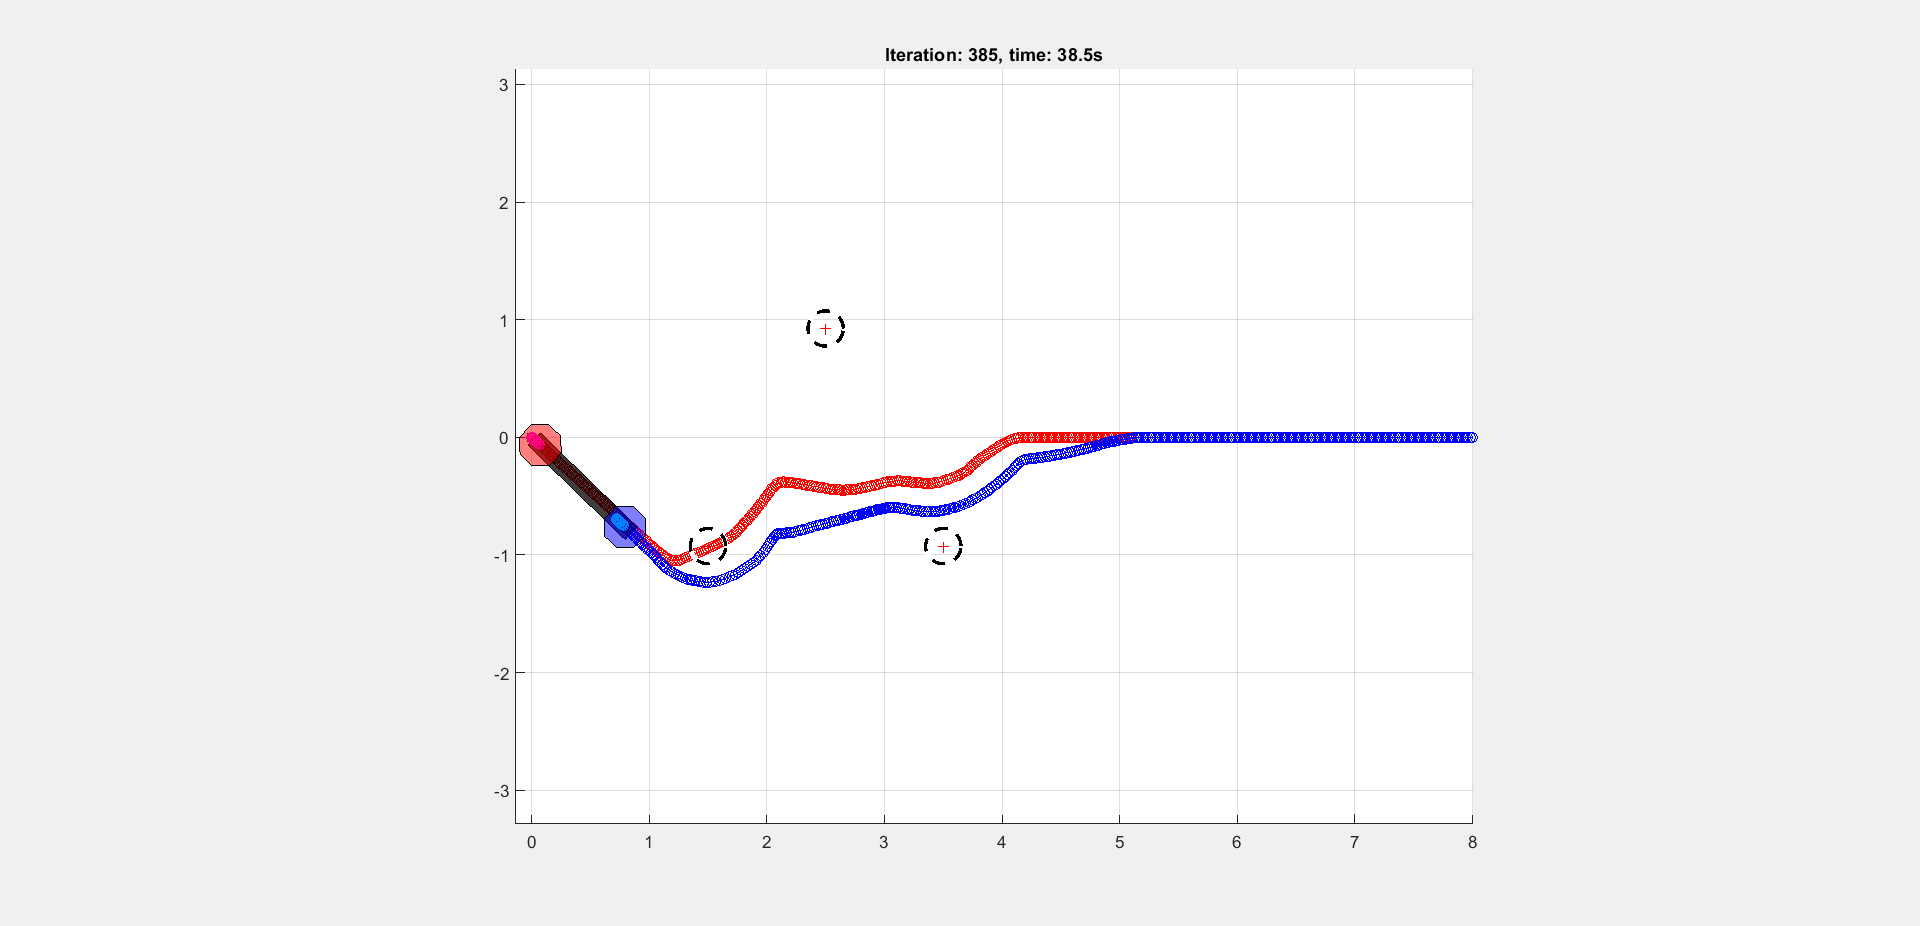

gifName = 'dynamic_' + environmentName + '.gif'; 
gifPath = fullfile(folderName, gifName);
frame_delay = sys.Ts;
dFig = figure("WindowState", "maximized"); 

if goal.move == true
    [~, ~, obstacles] = setupEnvironment(environmentName);
end

set(dFig,'Visible','on','PaperOrientation', 'landscape'); 
hold on; grid on; axis equal;
sp = SystemPlotter(leaderParams, followerParams, loadParams, x_l(:,1), x_f(:, 1), N, obstacles, goal);
tit = title("Iteration 1, time: 0s");

for ip = 1 : i - 1

    % Do the plotting
    sp.updateLeaderPath(x_l(:,ip), X_L_plot(:,:,ip));
    sp.updateFollowerPath(x_f(:,ip), X_F_plot(:,:,ip));
    sp.updateLoadPos(x_l(:,ip), x_f(:,ip), loadTheta_p(ip));

    if goal.move == true
        obstacles = updateMovingObs(obstacles);
        sp.updateObstacles(obstacles)
    end
    
    tit.String = "Iteration: " + num2str(ip) + ", time: " + num2str(ip*sys.Ts) + "s";
    sp.redraw();

    drawnow
    frame = getframe(dFig);
    im = frame2im(frame);
    [A, map] = rgb2ind(im, 256);

    if ip == 1
        imwrite(A, map, gifPath, 'gif', 'LoopCount', Inf, 'DelayTime', frame_delay);
    else
        imwrite(A, map, gifPath, 'gif', 'WriteMode', 'append', 'DelayTime', frame_delay);
    end
end

## Results plot

time = 0:sys.Ts:sys.Ts*(i-1);

load = x_f(1:2,i)+loadParams.loadShape;

th = 0:0.3:2*pi;
robot = (0.35/2)*[cos(th); sin(th)];

hFig = figure(); 
set(hFig,'Visible','on','position', [10,10,1200,600]);

#### Trajectory plot

subplot(3,2,[1 3 5])
hold on; grid on; axis equal; box on;

plot( x_l(1,1:i), x_l(2,1:i), "-o","Color", "red");
plot( x_f(1,1:i), x_f(2,1:i), "-o","Color", "blue");

plot(polyshape(x_l(1, i)+robot(1,:), x_l(2, i)+robot(2,:)),...
               'FaceColor',leaderParams.pos_color,'FaceAlpha',0.5);
plot(polyshape(x_f(1, i)+robot(1,:), x_f(2, i)+robot(2,:)),...
               'FaceColor',followerParams.pos_color,'FaceAlpha',0.5);


plotObstacles(obstacles);
plot(polyshape(load'), 'FaceColor',loadParams.color,'FaceAlpha',0.75);
title("\textbf{Leader-Follower Trajectory}","Interpreter","latex", "FontSize", 14)
xlabel("Coordinate x [m]","Interpreter","latex", "FontSize", 12)
ylabel("Coordinate y [m]","Interpreter","latex", "FontSize", 12)
legend("Leader Robot","Follower Robot","Location","southeast","Interpreter","latex", "FontSize", 12)

#### Formation error plot

subplot(3,2,2)
plot(time(1:end-1),real_d(1:i-1) - followerParams.d_FL, 'Color', [0.91,0.41,0.17], 'LineWidth', 0.8);
grid on; axis normal; box on;
xlabel("Time [s]", "Interpreter","latex", "FontSize", 12)
ylabel("$error$ [m]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Formation error}", "Interpreter","latex", "FontSize", 14)

#### Linear velocities plot

subplot(3,2,4)
hold on; grid on; axis normal; box on;
plot(time, u_l(1,1:i), 'red', 'LineWidth', 0.8);
plot(time, u_f(1,1:i), 'blue', 'LineWidth', 0.8);
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$v$ [m/s]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Linear velocities evolution}", "Interpreter","latex", "FontSize", 14)
legend("$v_{L}$","$v_{F}$","Interpreter","latex", "FontSize", 12, 'Location', 'best')

#### Angular velocities plot

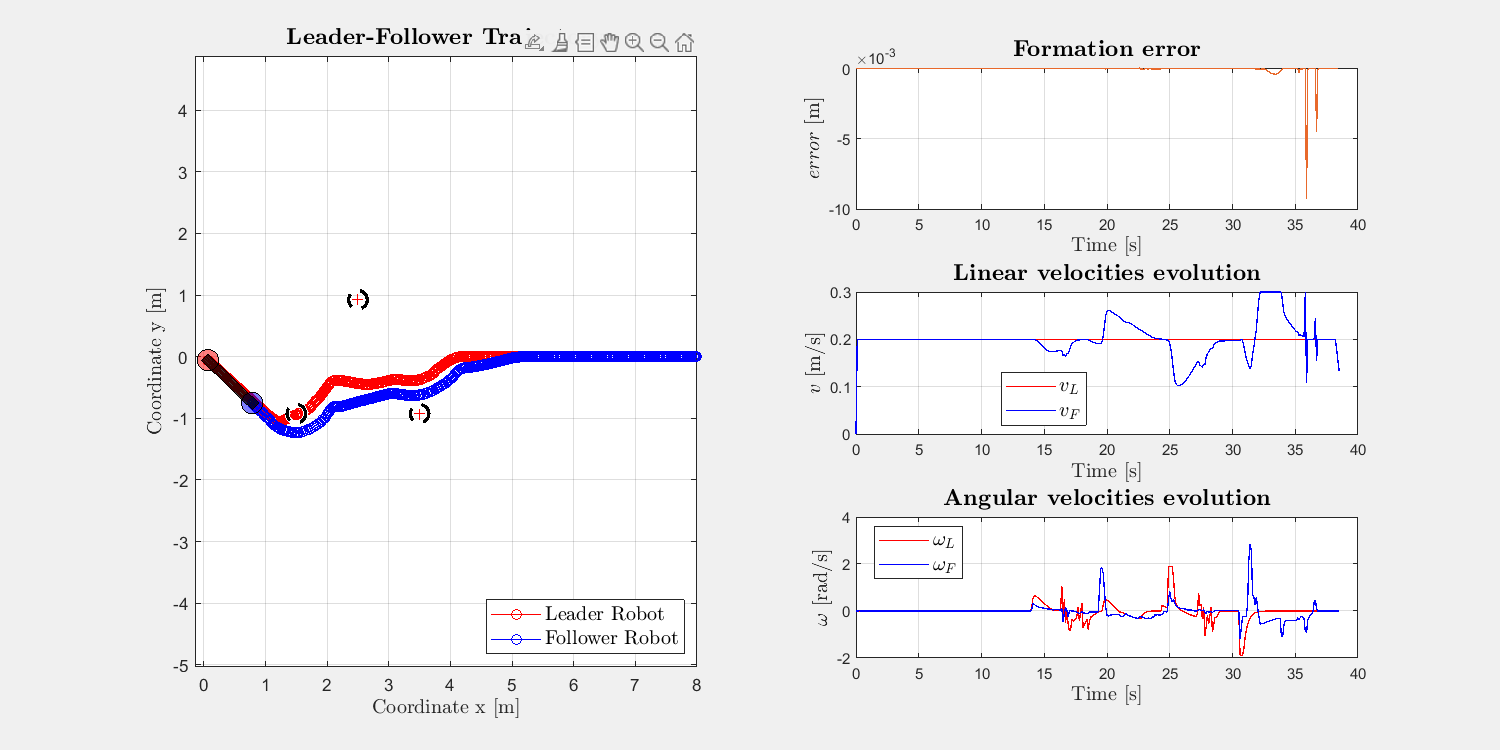

subplot(3,2,6)
hold on; grid on; axis normal; box on;
plot(time, u_l(2,1:i), 'Color', 'red', 'LineWidth', 0.8);
plot(time, u_f(2,1:i), 'Color', 'blue', 'LineWidth', 0.8);
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$\omega$ [rad/s]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Angular velocities evolution}", "Interpreter","latex", "FontSize", 14)
legend("$\omega_{L}$","$\omega_{F}$","Interpreter","latex", "FontSize", 12, 'Location', 'best')

## Saving plots

plotName = 'plot_' + environmentName + '.pdf'; 
plotPath = fullfile(folderName, plotName);

set(hFig,'Units','centimeters');
screenposition = get(gcf,'Position');
set(gcf,...
    'PaperPosition',[0 0 screenposition(3:4)],...
    'PaperSize',screenposition(3:4)+[0.5 0]);

print(hFig, plotPath, '-dpdf');